
% Only run once
clear
load('mnist_test.mat')
load('mnist_train.mat')

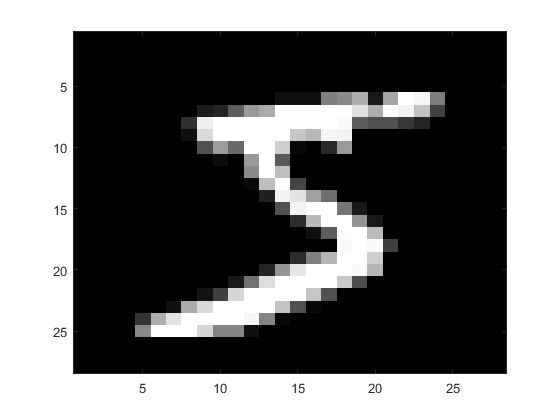

% Divide dataset into trainingset and testingset (Labels and Images)
images_train = mnisttrain{: , (2:end)};
labels_train = mnisttrain{: , 1};

images_test = mnisttest{: , (2:end)};
labels_test = mnisttest{: , 1};

% Display a rendomly selected image in grayscale
colormap gray
imagesc(reshape(images_train(1,:), 28,28)');

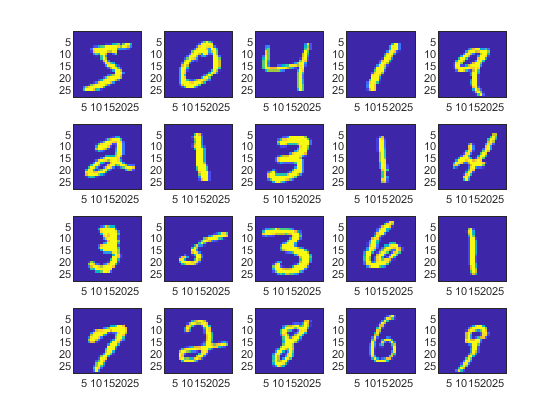


% Display 20 images of digits
figure;
perm = randperm(60000,20);
for i = 1:20
 subplot(4,5,i);
 imagesc(reshape(images_train(i,:),28,28)')
end


% Create and train machinelearning models with different K-nearest
% neighbours, to compare performance
model1 = fitcknn(images_train, labels_train, "NumNeighbors", 1, "Standardize", 1)

model1 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 60000
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


model5 = fitcknn(images_train, labels_train, "NumNeighbors", 5, "Standardize", 1)

model5 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 60000
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


model9 = fitcknn(images_train, labels_train, "NumNeighbors", 9, "Standardize", 1)

model9 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 60000
                 Distance: 'euclidean'
             NumNeighbors: 9


  Properties, Methods


## Prediction phase (takes long time)

% Make pedictions based on the models on the testdata imageset
tic
prediction1 = predict(model1, images_test);
prediction5 = predict(model5, images_test);
prediction9 = predict(model9, images_test);
toc

Elapsed time is 664.916126 seconds.


## measuring accuracy

% Model Knn k = 1
% See previous assignment for explanation
correct1 = prediction1 == labels_test;
wrong1 = prediction1 ~= labels_test;
accuracy1 = sum(correct1) / numel(prediction1)

accuracy1 = 0.9434

missclassrate1 = sum(wrong1) / numel(prediction1)

missclassrate1 = 0.0566

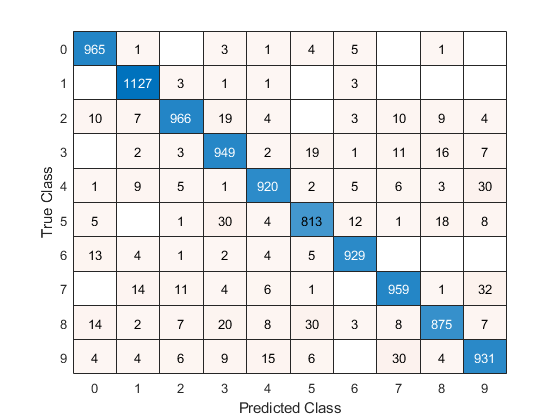

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 double]

  Show all properties


figure
confusionchart(labels_test, prediction1)


% Model Knn k = 5
correct5 = prediction5 == labels_test;
wrong5 = prediction5 ~= labels_test;
accuracy5 = sum(correct5) / numel(prediction5)

accuracy5 = 0.9445

missclassrate5 = sum(wrong5) / numel(prediction5)

missclassrate5 = 0.0555

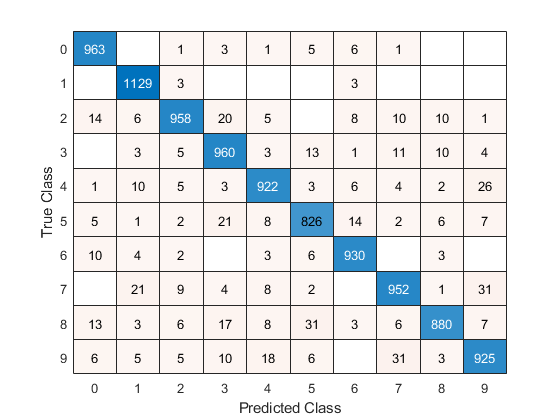

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 double]

  Show all properties


figure
confusionchart(labels_test, prediction5)


% Model Knn k = 9
correct9 = prediction9 == labels_test;
wrong9 = prediction9 ~= labels_test;
accuracy9 = sum(correct9) / numel(prediction9)

accuracy9 = 0.9428

missclassrate9 = sum(wrong9) / numel(prediction9)

missclassrate9 = 0.0572

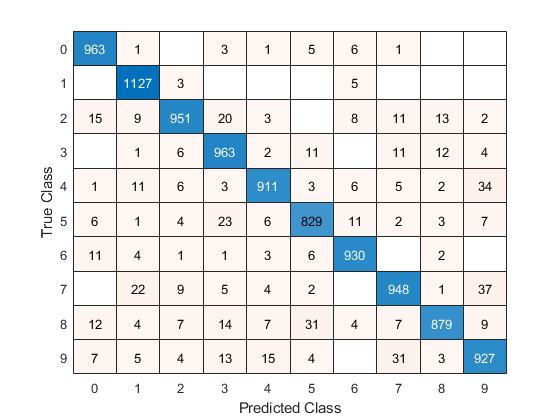

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 double]

  Show all properties


figure
confusionchart(labels_test, prediction9)